# Assignment 4: EEG Data Preprocessing with EEGLAB

## 1. Download the EEG data from the proved link.

% https://drive.google.com/file/d/1DeHj9WgkKhDr6Qni-EGfN4hybNDfSruq/view?usp=sharing

## 2. Import the data into MATLAB using EEGLAB functions.

[ALLEEG EEG CURRENTSET ALLCOM] = eeglab;

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\USER\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" v3.8.1 to the path
--------------------------------------------------------------------------------------------------------------------------------------------
%Equivalent command:
 erplab_running_version(   'tooltype', 'ERPLAB' 'version', '10.0' );
--------------------------------------------------------------------------------------------------------------------------------------------
Go back to ERPLAB menu

EEGLAB: adding "ERPLAB" v10.0 (see >> help eegplugin_erplab)
EEGLAB: adding "ICLabel" v1.4 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.91 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v5.3 (see >> help eegplugin_dipfit) - new vers

EEG = pop_biosig('C:\Users\USER\Desktop\CNELab\2023_Summer_Workshop\1. Matlab and EEGlab\A01E.gdf');

sopen mode is "OVERFLOWDETECTION:OFF"
Reading data in GDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Detected/removing 'EEG' prefix from channel labels


Importing data events...
eeg_checkset note: event field format 'edfplustype' made uniform
eeg_checkset note: creating the original event table (EEG.urevent)


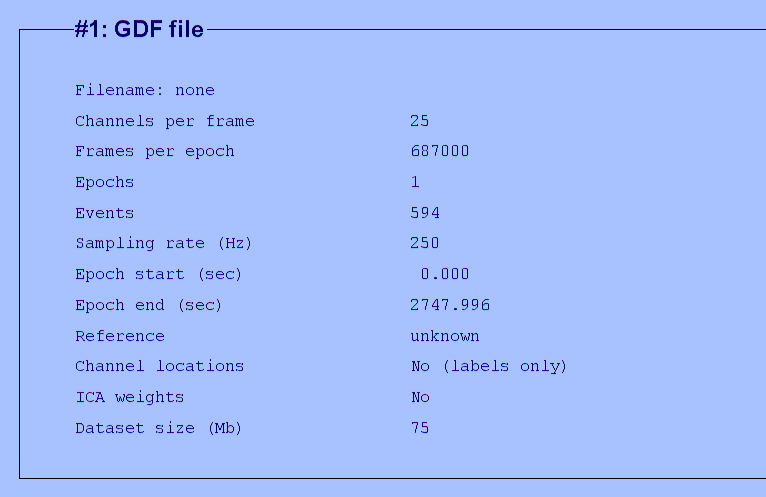

Creating a new ALLEEG dataset 1


You are using a new version of eegplot - if you encounter problems
type "edit eegplot.m" and change FORCE_EEGPLOT_LEGACY to true


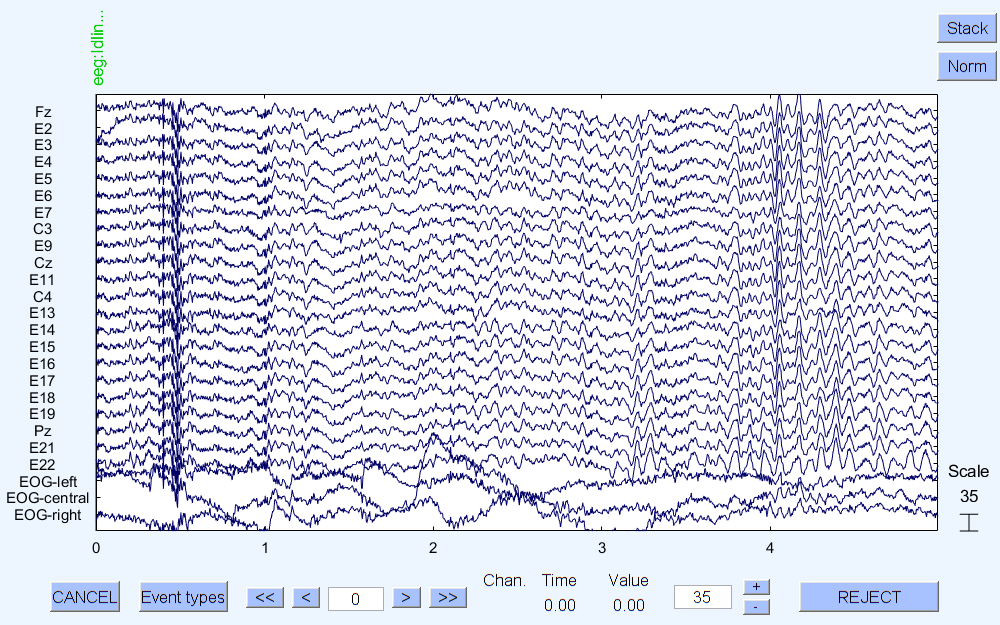

[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 0,'gui','off'); 

## 3. Apply a band-pass filter to the data to retain frequencies of interest (for instance, 0.5-50Hz).

EEG = pop_eegfiltnew(EEG, 'locutoff',0.5,'hicutoff',50,'plotfreqz',1);
[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 1,'gui','off'); 

## 4. Use the Artifact Subspace Reconstruction (ASR) method to clean the data.

EEG = pop_clean_rawdata(EEG, 'FlatlineCriterion',5,'ChannelCriterion',0.8,'LineNoiseCriterion',4,'Highpass','off','BurstCriterion',20,'WindowCriterion',0.25,'BurstRejection','on','Distance','Euclidian','WindowCriterionTolerances',[-Inf 7] );
[ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 2,'gui','off'); 

## 5. Perform Independent Component Analysis (ICA) to separate the data into independent components.

EEG = pop_runica(EEG, 'icatype', 'runica', 'extended',1,'interrupt','on');
[ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);

## 6. Identify event-related potentials (ERP) and plot the average ERP for a specified event type.

pop_saveh( ALLCOM, 'eeglabhist.m', 'C:\Users\USER\Desktop\CNELab\2023_Summer_Workshop\1. Matlab and EEGlab\');

Saving the EEGLAB session command history...


EEG = pop_epoch( EEG, {  }, [-1  2], 'newname', 'CNE epochs', 'epochinfo', 'yes');

pop_epoch():423 epochs selected
Epoching...
pop_epoch():423 epochs generated
Scaling components to RMS microvolt
Scaling components to RMS microvolt
pop_epoch(): checking epochs for data discontinuity


Command executed by pop_erpimage:
 
 erpimage( mean(EEG.data([1], :),1), ones(1, EEG.trials)*EEG.xmax*1000, linspace(EEG.xmin*1000, EEG.xmax*1000, EEG.pnts), 'Fz', 10, 1 , 'yerplabel', '\muV', 'erp', 'on', 'cbar', 'on', 'topo', { [1]' optchanlocs optchaninfo });
 
Plotting input data as 423 epochs of 750 frames sampled at 250.0 Hz.
Sorting data on input sortvar.
100.00% of the trials (i.e., 423 out of 423) have the same sortvar value as at least one other trial.
Distribution of number ties per unique value of sortvar:
Min: 423, 25th ptile: 423, Median: 423, 75th ptile: 423, Max: 423

Smoothing the sorted epochs with a 10-epoch moving window.
  and a decimation factor of 1
The caxis range will be the sym. abs. data range -> [-21.229,21.229].
Data will be plotted between -1000 and 1996 ms.
Output data will be 750 frames by 414 smoothed trials.
Outtrials: 6.00 to 419.00
Not all sortvar values within time vector limits: 
        outliers will be shown at nearest limit.
Overplotting sorted 

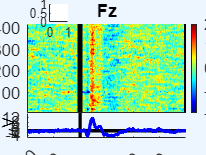

figure; pop_erpimage(EEG,1, [1],[[]],'Fz',10,1,{},[],'' ,'yerplabel','\muV','erp','on','cbar','on','topo', { [1] EEG.chanlocs EEG.chaninfo } );

Plotting data using axis size [0.05,0.08]
limits: [xmin,xmax,ymin,ymax] = [-1000.0 1996.0 -14.59 14.59]
Plotting 1 traces of 750 frames with colors: 'b' 
trace 1:  1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25


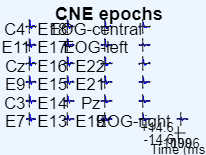

figure; pop_plottopo(EEG, [1:25] , 'CNE epochs', 0, 'ydir',1);

eeglab redraw;

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\USER\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" v3.8.1 to the path
--------------------------------------------------------------------------------------------------------------------------------------------
%Equivalent command:
 erplab_running_version(   'tooltype', 'ERPLAB' 'version', '10.0' );
--------------------------------------------------------------------------------------------------------------------------------------------
Go back to ERPLAB menu

EEGLAB: adding "ERPLAB" v10.0 (see >> help eegplugin_erplab)
EEGLAB: adding "ICLabel" v1.4 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.91 (see >> help eegplugin_clean_rawdata) - new version 2.8 available
EEGLAB: adding "dipfit" v5.3 (see >> help eegplugin_dipfit) - new vers

Scaling components to RMS microvolt
Scaling components to RMS microvolt
